# CTA PROCESSING CODE V1.0 (ACTUAL CHANNEL ARRANGEMENT)

Developed by: Ricardo Quiros, January 2018 Requierements: nothing...yet First real Train in this old dataset is 4

%Orignal Channel Arrangement (As labeled) [As in real life]
%  Cha1->Wheel Counter1    [OK]
%  Cha2->Wheel Counter2    [OK]
%  Cha3->Vert Near 2       [Horz     Near 2]
%  Cha4->Vert Far  2       [Horz     Far  2]
%  Cha5->Vert Near 2       [Horz     Near 1]
%  Cha6->Vert Far  2       [Horz     Far  1]
%  Cha7->Horz Near 1       [Vertical Near 2]
%  Cha8->Horz Far  1       [Vertical Far  2]

## Code Initizalizing

clear
close all;
clc
DataPath = pwd;
cd(DataPath);
directory=dir('*.txt'); %Unsorted filestructure
nTrains=length(directory);
time=0:0.0005:20-0.0005;
timeStamp(nTrains) = datetime;
speed(nTrains)=NaN';
nAxles(nTrains)=NaN';
fs=2000;
wheelFilt=designfilt('lowpassiir','FilterOrder',15,'PassbandFrequency',750,'PassbandRipple',0.0001,'SampleRate',2000);
calibF=   [1;...         %WheelC1
    1;...                %WheelC2
    231998.2797;...      %Horz Near 2
    -242373.513;...      %Horz Far  2
    259156.1521;...      %Vert Near 2
    265274.8107;...      %Vert Far  2
    1;...                %Vert Near 1
    1];                  %Vert Far  1

## Get TimeStamps

for i=1:nTrains
    timeStamp(i)=datetime(directory(i).name(9:end-4),'InputFormat','yyyyMMddHHmmss');
end
timeStamp=timeStamp';
axleInfo=table;
trainInfo=table;

## Identify trains broken in 2 files (Sometimes they go too slow and file gets splitted, its not worth to try to merge the files, data is generally lost. Files are ignored)

diffBetweenTrains=[seconds(diff(timeStamp));1000];
 ignoreFiles=[1:35,275];                                     %MANUALLY IGNORED FILES
 for i=1:length(diffBetweenTrains)
     if diffBetweenTrains(i)<=30
         ignoreFiles=[ignoreFiles,[i,i-1]];
     end
 end  
ignoreFiles=sort(ignoreFiles)';
clearvars diffBetweenTrains

## File Processsing

for i=1:nTrains
%      if ~ismember(i,ignoreFiles)

## ReadFile

        filename = strcat(DataPath, '/', directory(i).name);
        fid=fopen(filename);
        fileData= textscan(fid,'%f%f%f%f%f%f%f%f','HeaderLines',1);
        fclose(fid);
        TrainPassData=zeros(40000,8);
        %Baseline Correction and Filetering
        for q=1:8
            TrainPassData(:,q)=fileData{1,q};
            TrainPassData(:,q)=TrainPassData(:,q)-mean(TrainPassData(1:500,q));
            TrainPassData(:,q)=TrainPassData(:,q).*calibF(q);
            Filtered(:,q)=filtfilt(wheelFilt,TrainPassData(:,q));
            Filtered(1:1000,q)=0;
            Filtered(end-1000:end,q)=0;
            Filtered(Filtered<0)=0;
        end
        clearvars fileData fid filename q

## Speed processing

        prominence=1.25;
        distance=150;
        [WC1_pks,WC1_locs] = findpeaks(-TrainPassData(:,1),'MinPeakProminence',prominence,'MinPeakDistance',distance);
        [WC2_pks,WC2_locs] = findpeaks(-TrainPassData(:,2),'MinPeakProminence',prominence,'MinPeakDistance',distance);
        nAxles1=length(WC1_locs);
        nAxles2=length(WC2_locs);
        difPeaks=WC1_locs-WC2_locs; %Difference in number of samples between peaks (Same axles)
        avSpaSec=abs(median(difPeaks))/fs; %With known sample rate, we can convert from number of Samples to seconds
        speed(i)=131/avSpaSec*0.0036/1.614; %%Sensors are separated 131mm, so this is a conversion from mm/sec to km/h and then mph (Praise the American way)
        nAxles(i)=nAxles1;
        if isnan(speed(i))
            nAxles(i)=NaN;              %If speed cannot be calculated, its a false trigger, file gets ignored
            disp('FalseTrigger');
            continue
        elseif nAxles(i)~=32            %If Axles are not 32, skip the file
            continue
        else
            disp(speed(i));
        end

   23.3755



        clearvars difPeaks avSpaSam avSpaSec nAxles1 nAxles2 fid distance prominence

## Peak processing (Verticals)

        maxDatapoint=max(WC1_locs)+2000;
        if maxDatapoint<40000
            Filtered(maxDatapoint:end,5)=0;
            Filtered(maxDatapoint:end,6)=0;
        end
        prominence=4.5;
        distance=200;
        [V1_pks,V1_locs] = findpeaks(Filtered(:,5),'MinPeakProminence',prominence,'MinPeakDistance',distance); %Near
        [V2_pks,V2_locs] = findpeaks(Filtered(:,6),'MinPeakProminence',prominence,'MinPeakDistance',distance); %Far
        t=1;
        while t<50          %If not enough peaks are found, the code will try to adjust the parameters to make 32 peaks be detected, either increase or decrease the prominance and minpeak distance
            if length(V1_pks)>32
                clearvars V1_pks V1_locs
                prominence=prominence+0.2;
                [V1_pks,V1_locs]=findpeaks(Filtered(:,5),'MinPeakProminence',prominence,'MinPeakDistance',distance);
                t=t+1;
            elseif length(V1_pks)<32
                clearvars V1_pks V1_locs
                prominence=prominence-0.2;
                [V1_pks,V1_locs]=findpeaks(Filtered(:,5),'MinPeakProminence',prominence,'MinPeakDistance',distance);
                t=t+1;
            else
                prominence=4.5;
                t=100;
            end
            t=t+1;
        end
        if t==51 %If everything fails....just give me 32, we'll deal with that file later
            prominence=3;
            [V1_pks,V1_locs]=findpeaks(Filtered(:,5),'MinPeakProminence',prominence,'MinPeakDistance',distance,'NPeaks',32);
            disp(strcat('CHECK THIS ONE MANUALLY',int2str(i)))
        end
        t=1;
        while t<50
            if length(V2_pks)>32
                clearvars V2_pks V2_locs
                prominence=prominence+0.2;
                [V2_pks,V2_locs]=findpeaks(Filtered(:,6),'MinPeakProminence',prominence,'MinPeakDistance',distance);
                t=t+1;
            elseif length(V2_pks)<32
                clearvars V2_pks V2_locs
                prominence=prominence-0.2;
                [V2_pks,V2_locs]=findpeaks(Filtered(:,6),'MinPeakProminence',prominence,'MinPeakDistance',distance);
                t=t+1;
            else
                prominence=5;
                t=100;
            end
            t=t+1;
        end
        if t==51 %If everything fails....just give me 32, we'll deal with that file later
            prominence=3;
            [V2_pks,V2_locs]=findpeaks(Filtered(:,6),'MinPeakProminence',prominence,'MinPeakDistance',distance,'NPeaks',32);
            disp(strcat('CHECK THIS ONE MANUALLY_',int2str(i)))
        end
        clearvars distance prominence t

## Peak processing (Laterals)---Pulling at the same vertical peak locations

        L1_pks=TrainPassData(V1_locs,3);
        L2_pks=TrainPassData(V1_locs,4);

## Save Data

        trainNumber=ones(32,1)*i;
        trainDate(1:32,1)=timeStamp(i);
        trainSpeed=ones(32,1)*speed(i);
        trainAxle=[1:32]';
        trainPeaks=table(V1_pks,V2_pks,L1_pks,L2_pks);
        indTrain=[table(trainNumber,trainDate,trainSpeed,trainAxle),trainPeaks];
        singTrain=table(i,timeStamp(i),speed(i),'VariableNames',{'TrainNumber','TimeStamp','Speed'});
        clearvars trainNumber trainDate trainSpeed trainAxle

## All train Info

        axleInfo=[axleInfo;indTrain];
        disp(axleInfo);
        trainInfo=[trainInfo;singTrain]; 
        disp(trainInfo);
       
%     else
%         speed(i)=NaN;
%         nAxles(i)=NaN;
%         disp('Ignored File');
%      end
end

## Plot

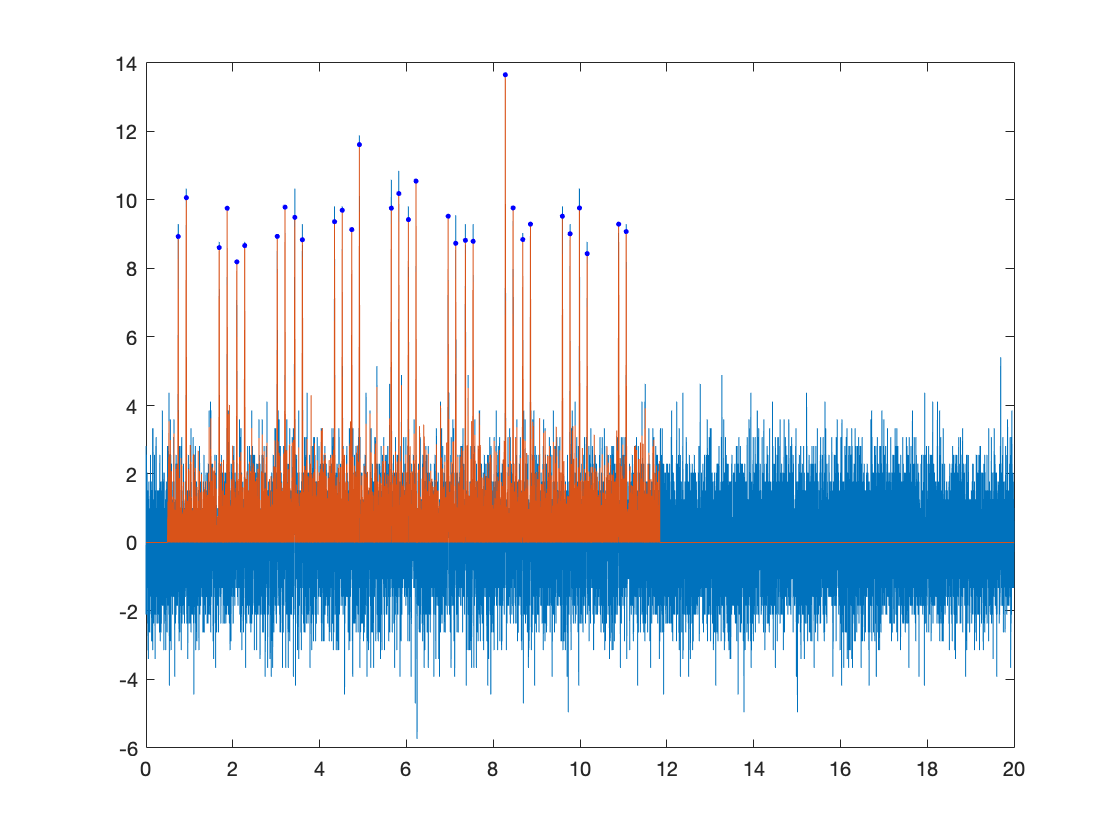

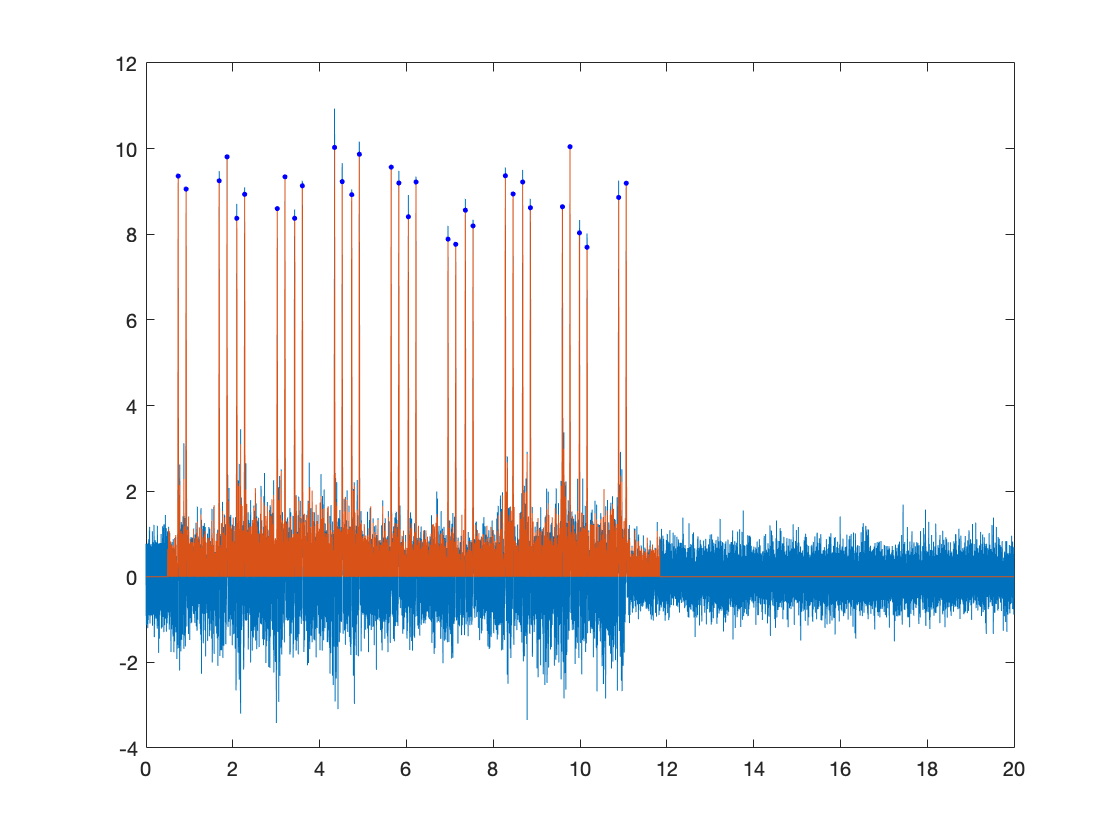

figure
plot(time,TrainPassData(:,5),time,Filtered(:,5),V1_locs/2000,V1_pks,'b.');
savefig('1.fig')
figure
plot(time,TrainPassData(:,6),time,Filtered(:,6),V2_locs/2000,V2_pks,'b.');
savefig('2.fig')


clearvars -except axleInfo trainInfo